DNN

% add folder with helper function tp to path
function_folder = fullfile(pwd, 'functions');
addpath(function_folder)

cfg = struct;
cfg.subNums = 4:19;
cfg.n = length(cfg.subNums);
cfg.categories = {'bathroom', 'kitchen'};
cfg.exp_num = 1;
cfg.colormaps = load('white_zero_colormap.mat');
d = struct;
images = load_images(cfg);

Loaded image: 004_bath1_3D.png
Loaded image: 004_bath2_3D.png
Loaded image: 004_bath3_3D.png
Loaded image: 005_bath1_3D.png
Loaded image: 005_bath2_3D.png
Loaded image: 005_bath3_3D.png
Loaded image: 006_bath1_3D.png
Loaded image: 006_bath2_3D.png
Loaded image: 006_bath3_3D.png
Loaded image: 007_bath1_3D.png
Loaded image: 007_bath2_3D.png
Loaded image: 007_bath3_3D.png
Loaded image: 008_bath1_3D.png
Loaded image: 008_bath2_3D.png
Loaded image: 008_bath3_3D.png
Loaded image: 009_bath1_3D.png
Loaded image: 009_bath2_3D.png
Loaded image: 009_bath3_3D.png
Loaded image: 010_bath1_3D.png
Loaded image: 010_bath2_3D.png
Loaded image: 010_bath3_3D.png
Loaded image: 011_bath1_3D.png
Loaded image: 011_bath2_3D.png
Loaded image: 011_bath3_3D.png
Loaded image: 012_bath1_3D.png
Loaded image: 012_bath2_3D.png
Loaded image: 012_bath3_3D.png
Loaded image: 013_bath1_3D.png
Loaded image: 013_bath2_3D.png
Loaded image: 013_bath3_3D.png
Loaded image: 014_bath1_3D.png
Loaded image: 014_bath2_3D.png
Loaded i

analysis typical - layer #1 - category: bathroom
Length of labels do not match matrix dimensions


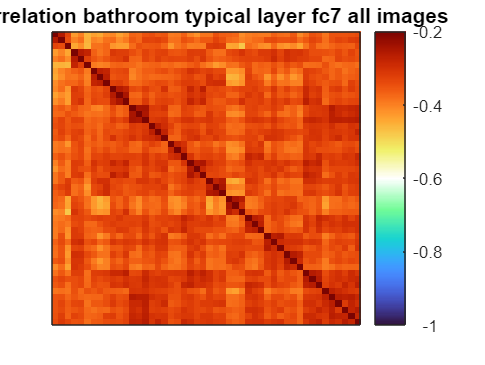

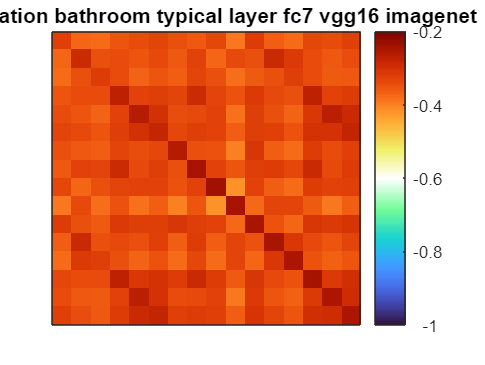

analysis typical - layer #1 - category: kitchen
Length of labels do not match matrix dimensions


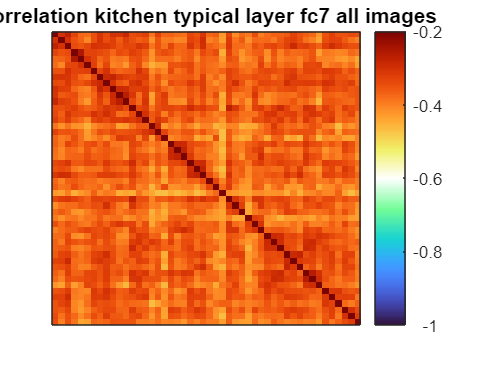

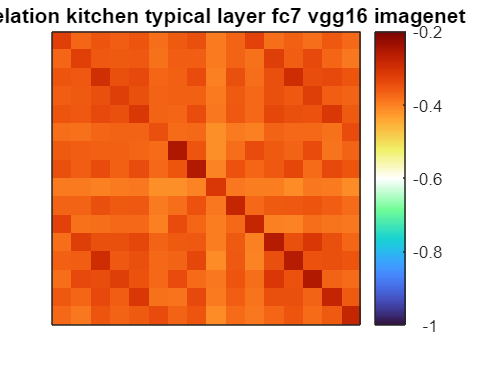


% typical images 
cfg.analysis_name = 'typical';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

analysis control - layer #1 - category: bathroom
Length of labels do not match matrix dimensions


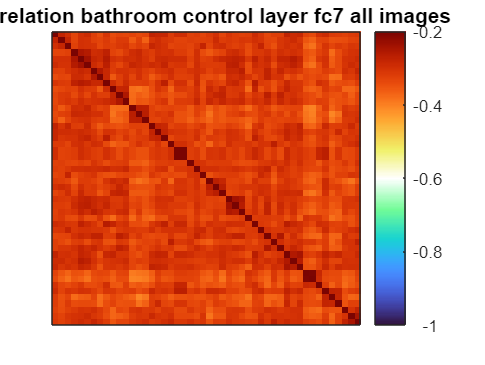

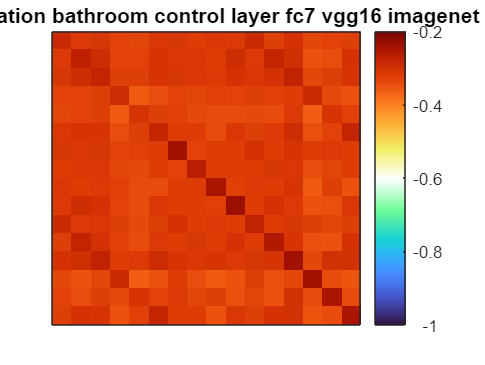

analysis control - layer #1 - category: kitchen
Length of labels do not match matrix dimensions


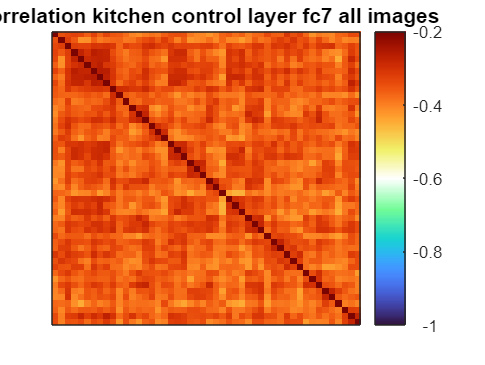

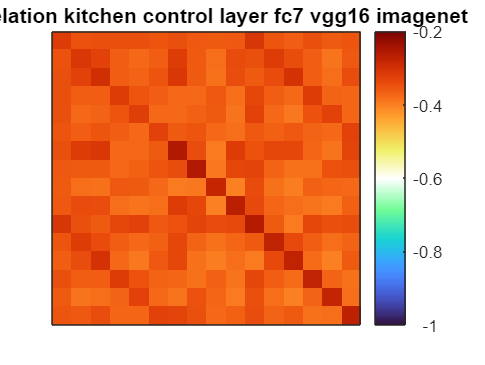


% control images 
cfg.analysis_name = 'control';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

Gaze

d = e_makeGDM(d, cfg);

Evaluating subject 004
Evaluating subject 005
Evaluating subject 006
Evaluating subject 007
Evaluating subject 008
Evaluating subject 009
Evaluating subject 010
Evaluating subject 011
Evaluating subject 012
Evaluating subject 013
Evaluating subject 014
Evaluating subject 015
Evaluating subject 016
Evaluating subject 017
Evaluating subject 018
Evaluating subject 019
 
Split-half reliablity for bathroom images
 
Single object dwell time
pearson r: 0.80166, p = 3.9041e-28
spearman r: 0.7683, p = 0
 
Fixation count
pearson r: 0.76913, p = 1.08e-24
spearman r: 0.74526, p = 1.6583e-22
 
Category dwell time
pearson r: 0.43239, p = 8.1523e-07
spearman r: 0.39202, p = 1.1242e-05
Evaluating subject 004
Evaluating subject 005
Evaluating subject 006
Evaluating subject 007
Evaluating subject 008
Evaluating subject 009
Evaluating subject 010
Evaluating subject 011
Evaluating subject 012
Evaluating subject 013
Evaluating subject 014
Evaluating subject 015
Evaluating subject 016
Evaluating subject 017

Plotting and saving inter-subject RDM for task:ObjectDwellsMulti and bathroom


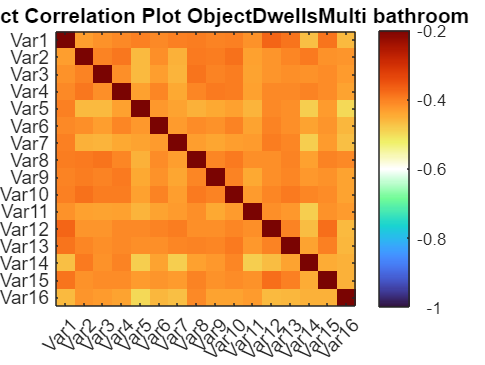

Plotting and saving inter-subject RDM for task:ObjectFixCount and bathroom


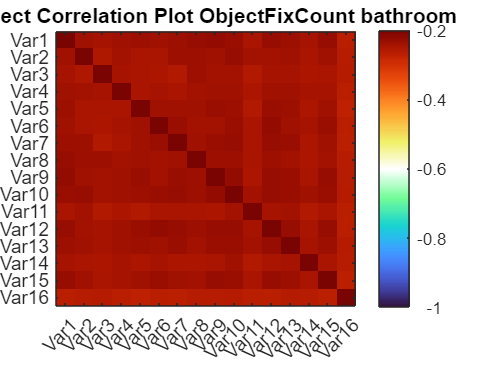

Plotting and saving inter-subject RDM for task:ObjectDwellsMultiCate and bathroom


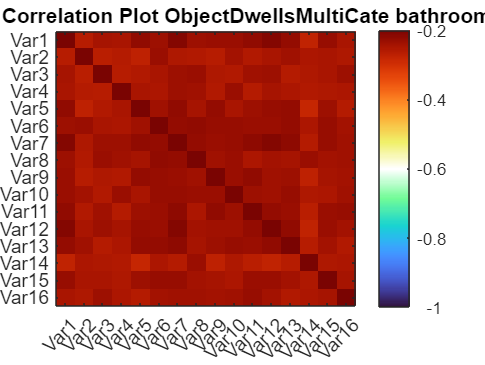

Plotting and saving inter-subject RDM for task:ObjectDwellsMulti and kitchen


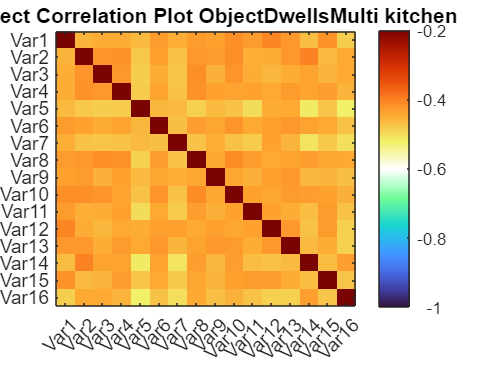

Plotting and saving inter-subject RDM for task:ObjectFixCount and kitchen


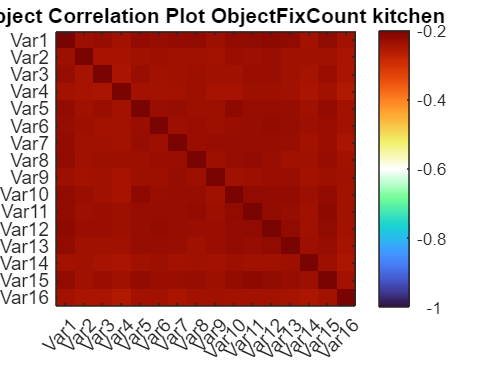

Plotting and saving inter-subject RDM for task:ObjectDwellsMultiCate and kitchen


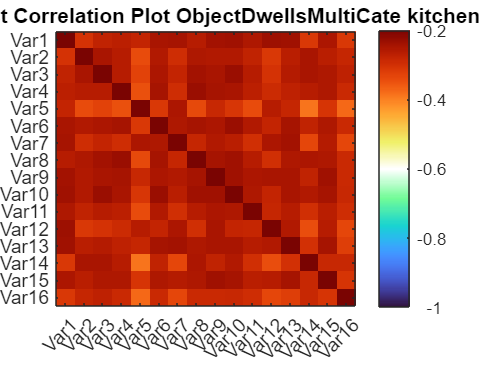

Compare categories



cfg.variables_of_interest = {'ObjectDwellsMulti', 'ObjectFixCount', 'ObjectDwellsMultiCate'};
[d] = intersub_cor(d, cfg);

Compare them

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of ObjectFixCount bathroom is done
20% of permutations of ObjectFixCount bathroom is done
30% of permutations of ObjectFixCount bathroom is done
40% of permutations of ObjectFixCount bathroom is done
50% of permutations of ObjectFixCount bathroom is done
60% of permutations of ObjectFixCount bathroom is done
70% of permutations of ObjectFixCount bathroom is done
80% of permutations of ObjectFixCount bathroom is done
90% of permutations of ObjectFixCount bathroom is done
100% of permutations of ObjectFixCount bathroom is done
Compare inter-subject RDM of ObjectFixCount with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of ObjectFixCount kitchen is done
20% of permutations of ObjectFixCount kitchen is done
30% of permutations of ObjectFixCount kitchen is done
40% of permutations of ObjectFixCount kitchen is done
50% of permutations

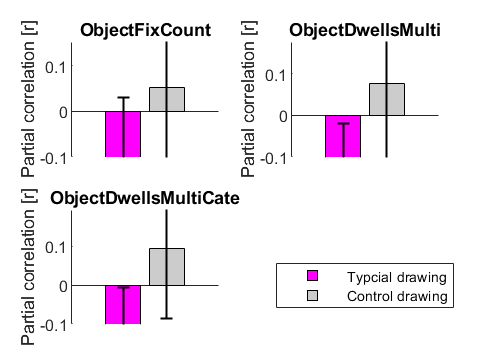

% preparation
cfg.partial_cor = 1;
cfg.plot_rdm = 0;
cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late','Control Images vgg16_imagenet Late'};
cfg.predictor_RDMs = {'typical_late', 'control_late'};
cfg.tasks_of_interest = {'ObjectFixCount', 'ObjectDwellsMulti', 'ObjectDwellsMultiCate'};
cfg.dnns = {'vgg16_imagenet'};
cfg.plot_type = 'bar';
cfg.show_single_cate = 0;
cfg.permutation_test = 1;
cfg.n_permutations = 100;
cfg.permutation_type = 'row_col_shuffle_pred';

cfg.partial_correlation_type = 'pearson';

d = compare_task_RDMs_to_predictor_RDMs(d, cfg);